# **First frame a[n] **

xn=[1 -4 3 8 2 7 3 5 1 8];
NN=10;
Xk=fft(xn);
fprintf('X[k]=\n');
disp(Xk);
an=[1 -4 3 8 2];
N=5;
Ak=fft(an);
fprintf('A[k]=\n');
disp(Ak);
bn=[-4 3 8 2 7];
Bk=zeros(1,5);
for m=0:N-1
Bk(m+1)=(Ak(m+1)-an(1)+bn(end)).*exp((1j*2*pi*m)./5);
end
fprintf('B[k]=\n');
disp(Bk);
cn=[3 8 2 7 3];
Ck=zeros(1,5);
for m=0:N-1
Ck(m+1)=(Bk(m+1)-bn(1)+cn(end)).*exp((1j*2*pi*m)./5);
end
fprintf('C[k]=\n');
disp(Ck);
dn=[8 2 7 3 5];
Dk=zeros(1,5);
for m=0:N-1
Dk(m+1)=(Ck(m+1)-cn(1)+dn(end)).*exp((1j*2*pi*m)./5);
end
fprintf('D[k]=\n');
disp(Dk);
en=[2 7 3 5 1];
Ek=zeros(1,5);
for m=0:N-1
Ek(m+1)=(Dk(m+1)-dn(1)+en(end)).*exp((1j*2*pi*m)./5);
end
fprintf('E[k]=\n');
disp(Ek);
fn=[7 3 5 1 8];
Fk=zeros(1,5);
for m=0:N-1
Fk(m+1)=(Ek(m+1)-en(1)+fn(end)).*exp((1j*2*pi*m)./5);
end
fprintf('F[k]=\n');
disp(Fk);

# **Global variable**


image =imread('car.jpg');

saveNameBefore ='Before.jpeg';
saveNameAfter = 'After.jpeg';

scaling=5; 

# **1.Find C8**

C8=findDCTMatrix(); %call function
inve=inv(C8);
transpo=C8';

transpo-inve; %%Check if inverse == transpose (10^-15 ~=0)

# **2. JPEG encoding**

grayImage = rgb2gray(image);
imwrite(grayImage,saveNameBefore );
grayImage = pading(grayImage);

**2.1.Block divide **

mySplit = SplitImage(grayImage); %call function
 

**2.2. DCT block **

blocksDCT = DCTBlock(mySplit,C8,0);  %call function

**2.3. Quantization **

load  'DCTQ'

JPEGRes = QuantJPEG(blocksDCT,DCTQ,scaling); %call function

# **3. JPEG decoding**

**3.1.Rescaling the data blocks **

rescaleIM=rescaling(JPEGRes,DCTQ,scaling);%call function

**3.2. DCT block inverse**

blocksIDCT = DCTBlock(rescaleIM,C8,1); %call function

**3.3. Merging the blocks **

JPEGImage =recombinesBlocks(blocksIDCT);%call function

# **4. Save the compressed image**

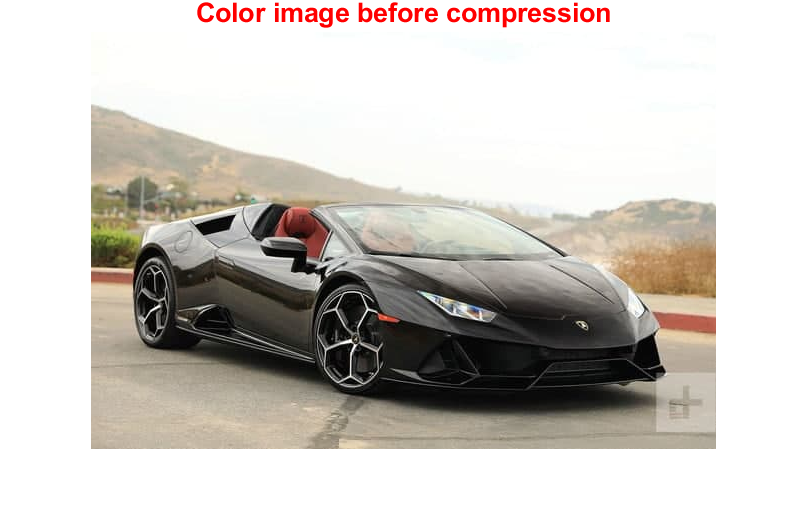

imwrite(JPEGImage, saveNameAfter);
imshow(image)
title('Color image before compression','FontSize',16,'color','red')

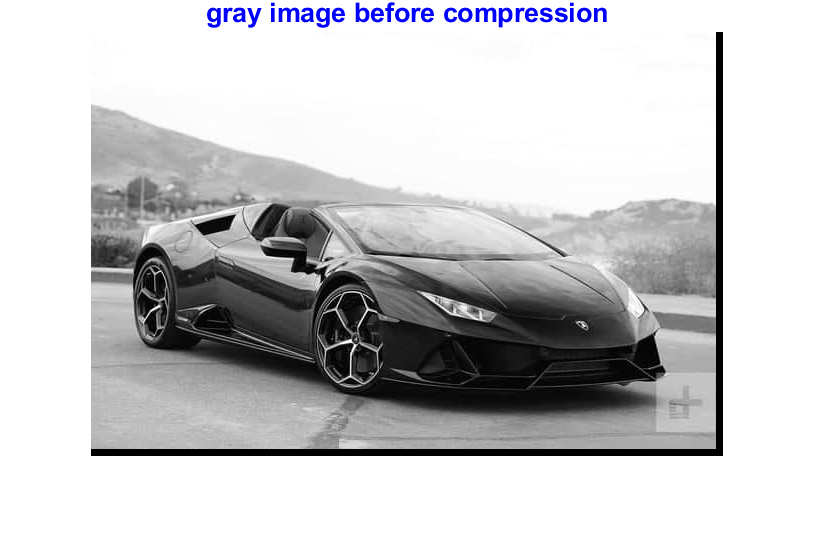

figure;
imshow(grayImage)
title('gray image before compression','FontSize',16,'color','blue')

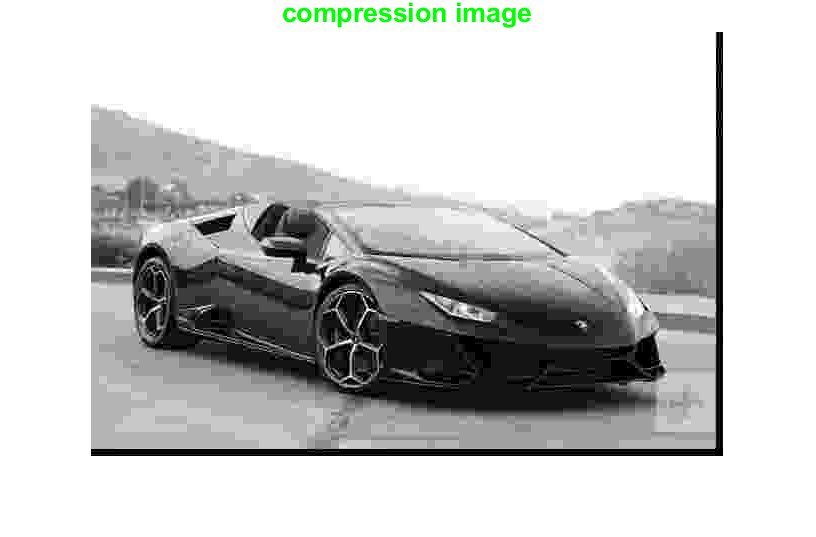

figure;
imshow(JPEGImage)
title('compression image','FontSize',16,'color','green')